Homework #08

## 1a

X=[ 4, 9, 8, 7, 1, 1, 1, 2, 1, 5, 4, 10, 9, 8, 2, 4;
5, 8, 8, 2, 9, 10, 1, 1, 2, 5, 6, 8, 7, 2, 9, 4];

Parameters:

% neighborhood kernel:
K_nearest=0.8;
K_other=0.1;

% learning rate:
eta=0.1;

Initial plot:

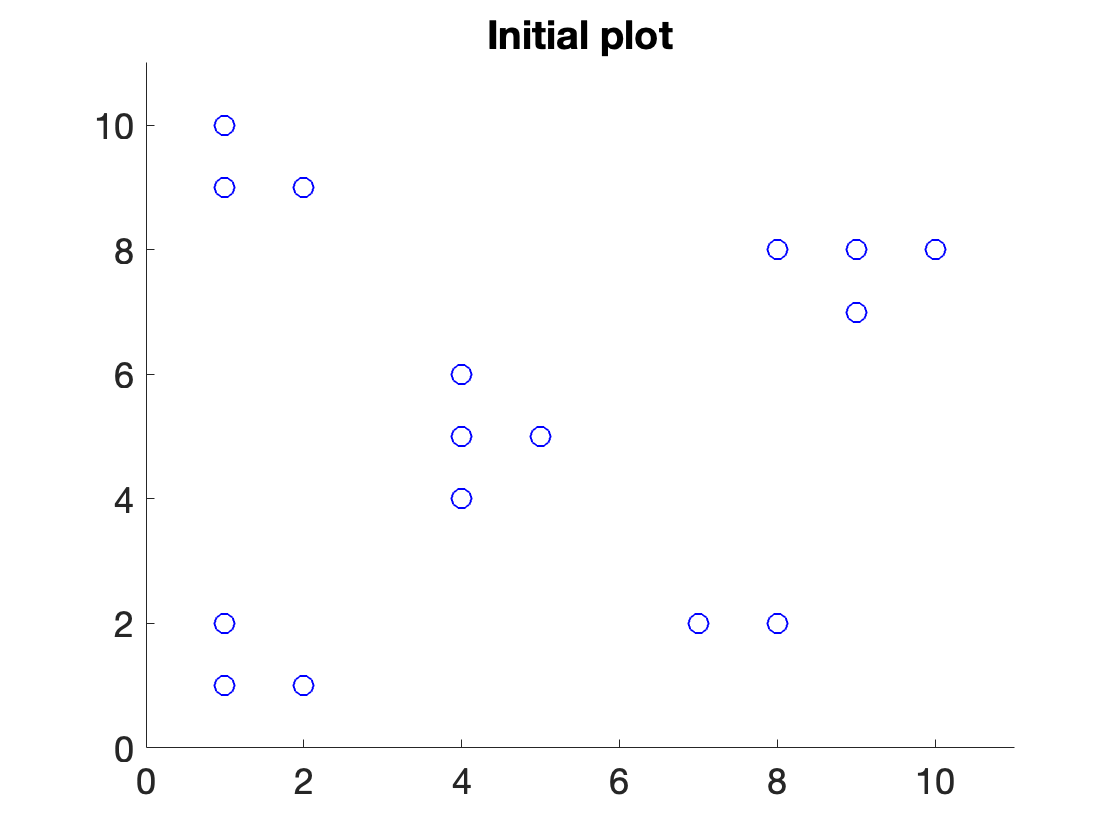

set(0,'defaulttextfontsize',18); set(0,'defaultaxesfontsize',18);
figure; clf; hold on; title('Initial plot')
xlim([0 11]); ylim([0 11]);

% plot datapoints
scatter(X(1,:),X(2,:),100,'bo');
hold off

Looks like 5ish clusters from the plot, we can try n=5

Reference pts:

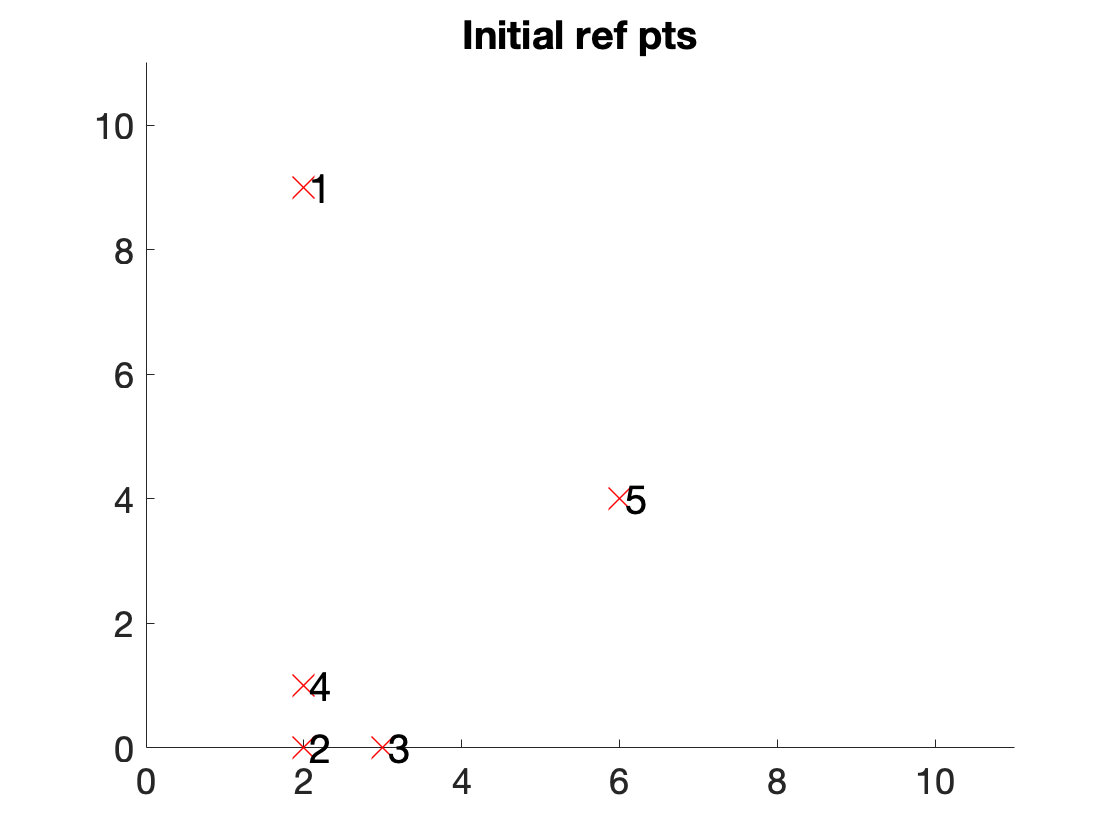

N_grid=5;
Xref=X(:, 6:6+N_grid-1);
for j=1:1:length(Xref)
    Xref(:,j)=Xref(:,j)+[1;-1];
end

% plot reference points:
figure; clf; hold on; title('Initial ref pts')
xlim([0 11]); ylim([0 11]);

href=scatter(Xref(1,:),Xref(2,:),200,'rx');
for ii=1:N_grid 
  h_ref_text(ii)=text(Xref(1,ii)+0.07,Xref(2,ii),num2str(ii),'FontSize',20);
end
hold off

First two iterations/datapoints in detail:

iepoch = 1 % 1st epoch only

iepoch = 1

Iteration: 1


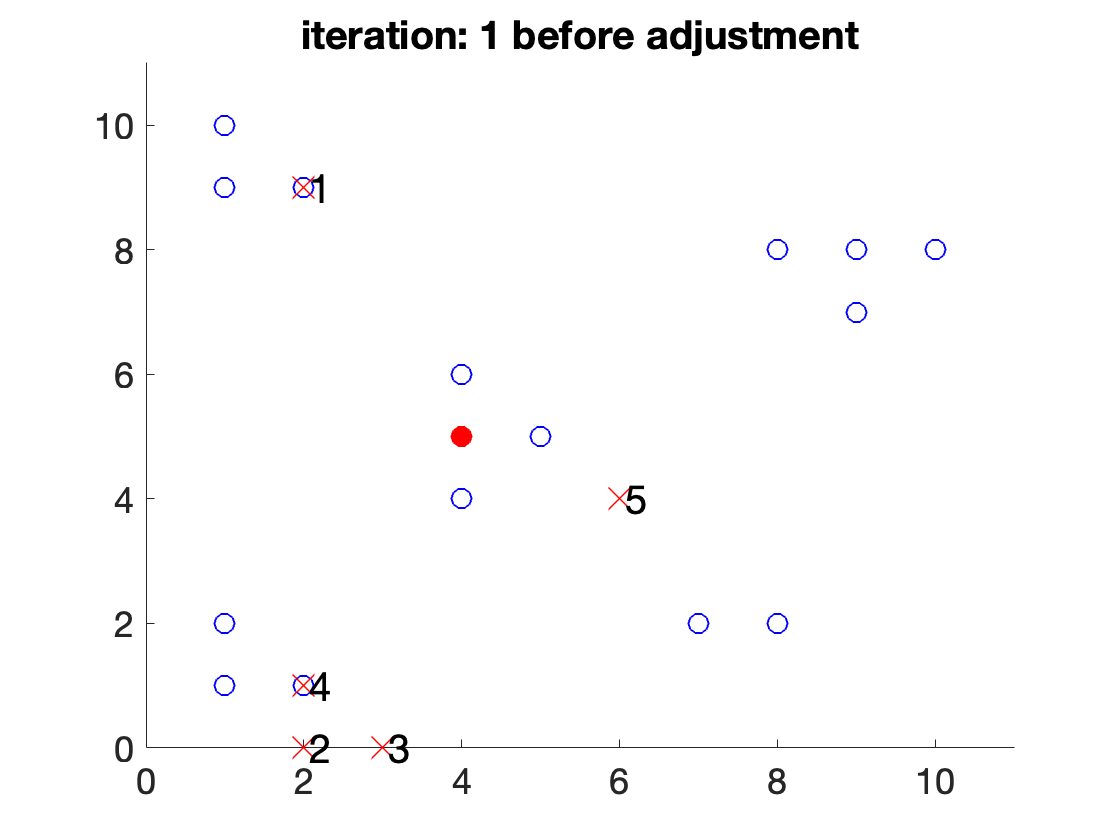

current datapoint in red is: 1


nearest ref point is: 1


nearest ref point adjusted by:


    0.1472
   -0.2944



neighbor ref point 5 adjusted by:


   -0.0198
    0.0099



neighbor ref point 2 adjusted by:


    0.0198
    0.0495



output adjusted new ref pts:


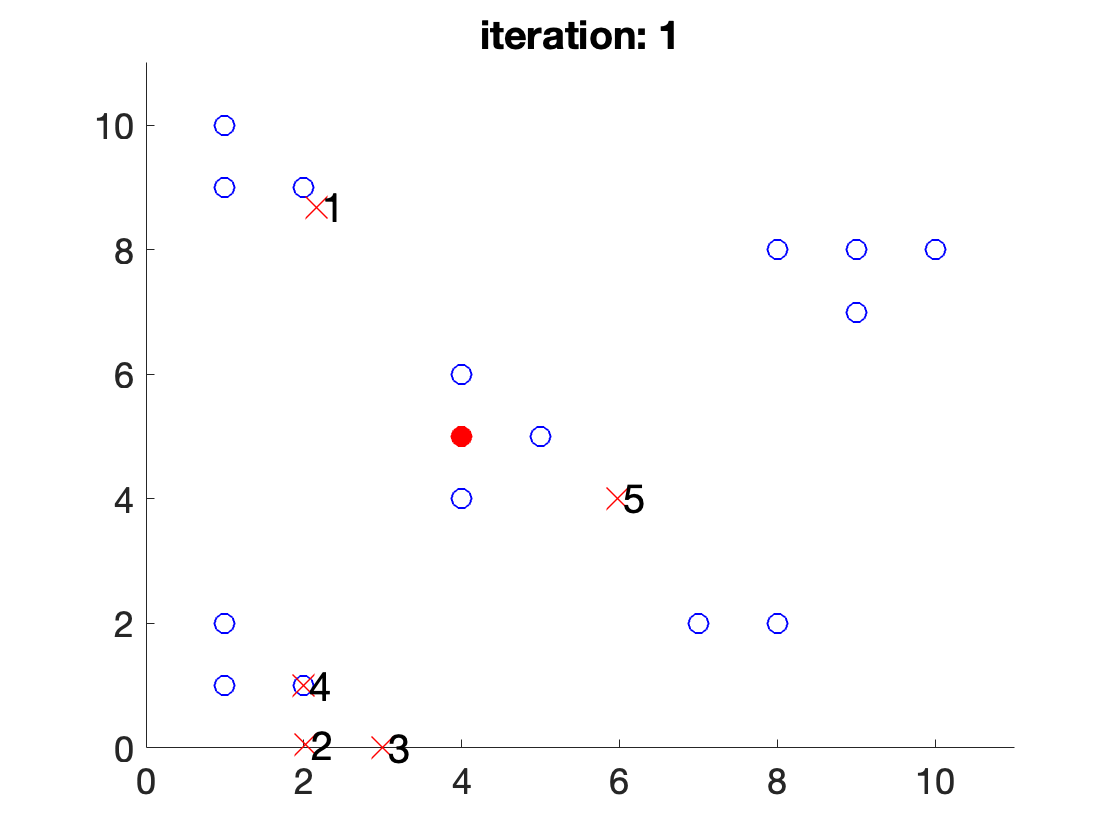

Iteration: 2


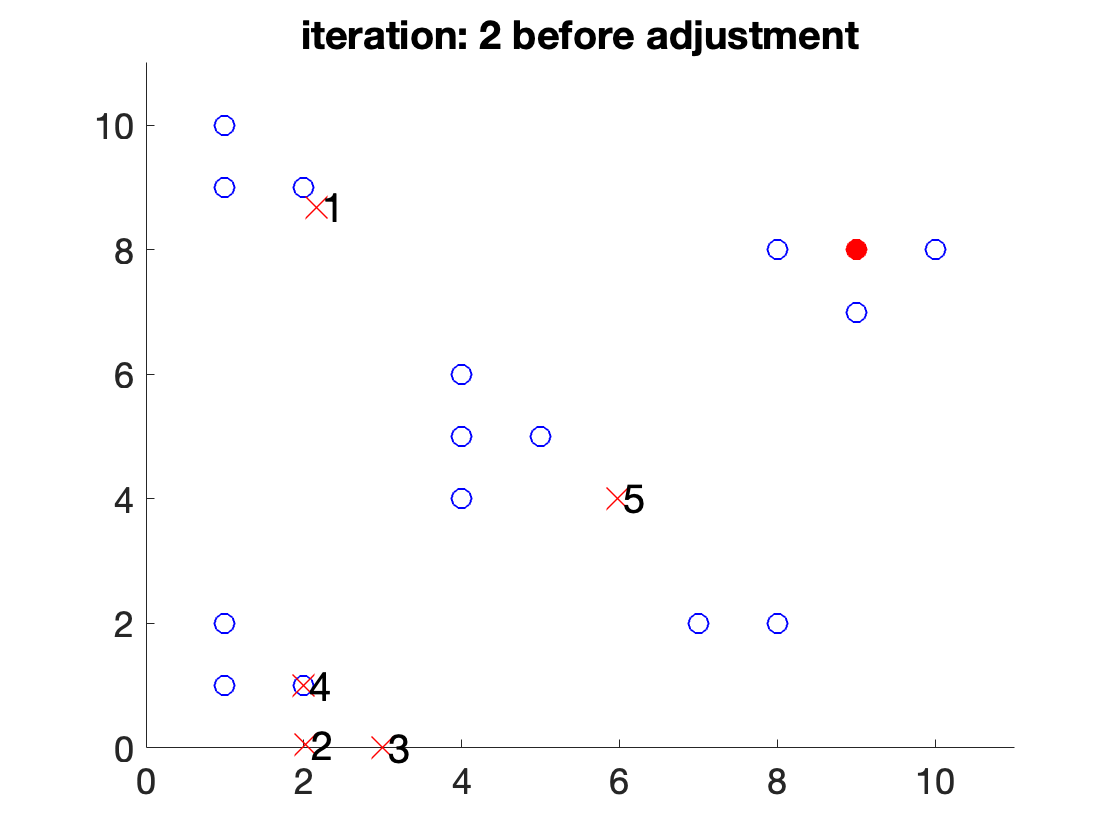

current datapoint in red is: 2


nearest ref point is: 1


nearest ref point adjusted by:


    0.5034
   -0.0500



neighbor ref point 5 adjusted by:


    0.0299
    0.0395



neighbor ref point 2 adjusted by:


    0.0691
    0.0787



output adjusted new ref pts:


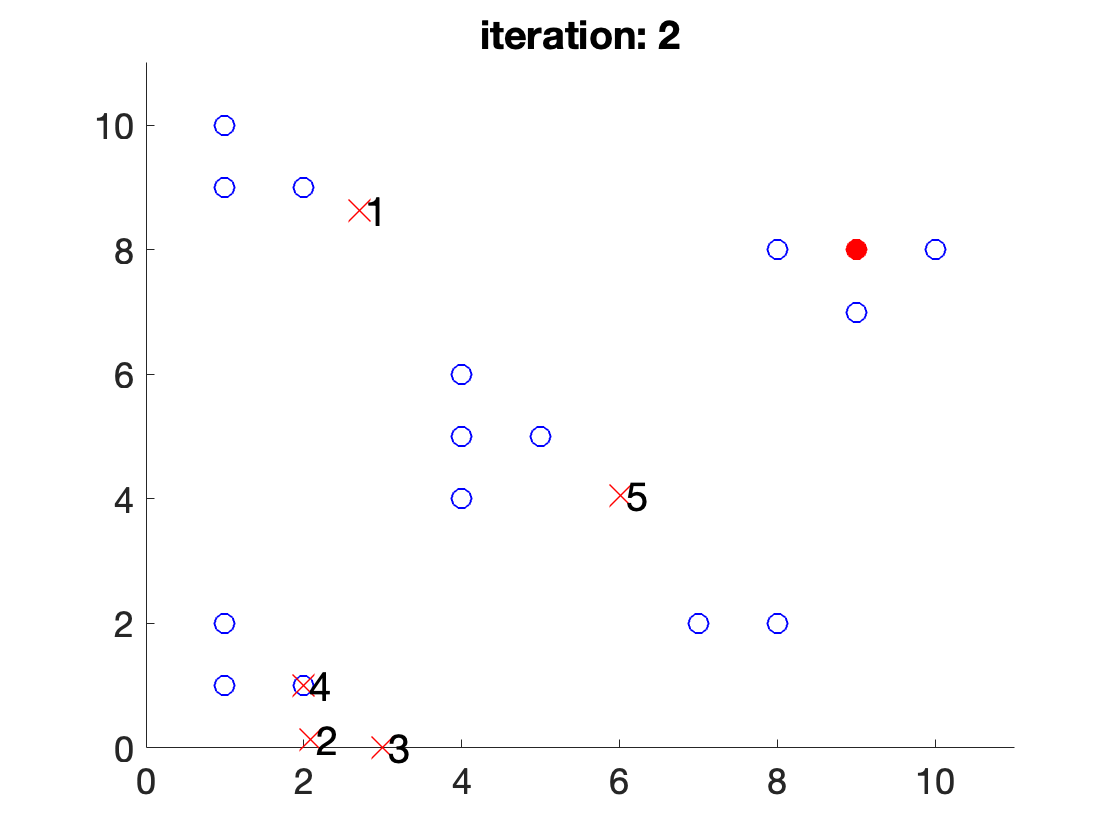


iter=0; % counter of data points being examined
for n=1:1:2
    iter = iter + 1;
    disp(['Iteration: ' num2str(iter)])
    
    % initialize plot
    set(0,'defaulttextfontsize',18); set(0,'defaultaxesfontsize',18);
    figure; clf; hold on; title(['iteration: ' num2str(iter) ' before adjustment'])
    xlim([0 11]); ylim([0 11]);
    
    % plot datapoints
    scatter(X(1,:),X(2,:),100,'bo');
    
    % draw current data point in red:
    h_current_data=scatter(X(1,n),X(2,n),100,'ro','MarkerFaceColor','r');
    
    % plot reference points:
    href=scatter(Xref(1,:),Xref(2,:),200,'rx');
    for ii=1:N_grid 
      h_ref_text(ii)=text(Xref(1,ii)+0.07,Xref(2,ii),num2str(ii),'FontSize',20);
    end
    hold off
    
    % name current data pt in red
    disp(['current datapoint in red is: ' num2str(n)])
    
    % find which reference point is nearest to current data point: 
    % out of the 4 reference pts
    [Dmin,I]=min([norm(X(:,n)-Xref(:,1)),norm(X(:,n)-Xref(:,2))...
                  ,norm(X(:,n)-Xref(:,3)),norm(X(:,n)-Xref(:,4))]);
    disp(['nearest ref point is: ' num2str(I)])
    
    % adjust the nearest reference point using the learning rate:
    Xref(:,I)=Xref(:,I)+eta*K_nearest*(X(:,n)-Xref(:,I));
    x0=Xref(:,I); dx=K_nearest*(X(:,n)-Xref(:,I)); dx=0.6*dx/norm(dx);
    disp(['nearest ref point adjusted by:'])
    disp(eta*K_nearest*(X(:,n)-Xref(:,I)))
    
    % adjust the other reference points using the specified kernel:
    nearest_neighbors_grid_space=[I-1,I+1];
    nearest_neighbors_grid_space(nearest_neighbors_grid_space==0)=N_grid;
    nearest_neighbors_grid_space(nearest_neighbors_grid_space==N_grid+1)=1;
    i1=0;
    for nn=nearest_neighbors_grid_space
      i1=i1+1;
      Xref(:,nn)=Xref(:,nn)+eta*K_other*(X(:,n)-Xref(:,nn));
      x0=Xref(:,nn); dx=K_nearest*(X(:,n)-Xref(:,nn)); dx=0.3*dx/norm(dx);
      disp(['neighbor ref point ' num2str(nn) ' adjusted by:'])
      disp(eta*K_other*(X(:,n)-Xref(:,nn)))
    end
    
    disp('output adjusted new ref pts:')
    
    % initialize plot
    set(0,'defaulttextfontsize',18); set(0,'defaultaxesfontsize',18);
    figure; clf; hold on; title(['iteration: ' num2str(iter)])
    xlim([0 11]); ylim([0 11]);
    
    % plot datapoints
    scatter(X(1,:),X(2,:),100,'bo');
    
    % draw current data point in red:
    h_current_data=scatter(X(1,n),X(2,n),100,'ro','MarkerFaceColor','r');
    
    % plot reference points:
    href=scatter(Xref(1,:),Xref(2,:),200,'rx');
    for ii=1:N_grid 
      h_ref_text(ii)=text(Xref(1,ii)+0.07,Xref(2,ii),num2str(ii),'FontSize',20);
    end
    hold off
    
    disp('')
    
end

Iterating through all data pts:

for iepoch = 1:1:30
iter=0; % counter of data points being examined
for n=1:length(X(1,:))
    iter = iter + 1;
    
    % find which reference point is nearest to current data point: 
    % out of the 4 reference pts
    [Dmin,I]=min([norm(X(:,n)-Xref(:,1)),norm(X(:,n)-Xref(:,2))...
                  ,norm(X(:,n)-Xref(:,3)),norm(X(:,n)-Xref(:,4)),norm(X(:,n)-Xref(:,4))]);
    
    % adjust the nearest reference point using the learning rate:
    Xref(:,I)=Xref(:,I)+eta*K_nearest*(X(:,n)-Xref(:,I));
    x0=Xref(:,I); dx=K_nearest*(X(:,n)-Xref(:,I)); dx=0.6*dx/norm(dx);
    
    % adjust the other reference points using the specified kernel:
    nearest_neighbors_grid_space=[I-1,I+1];
    nearest_neighbors_grid_space(nearest_neighbors_grid_space==0)=N_grid;
    nearest_neighbors_grid_space(nearest_neighbors_grid_space==N_grid+1)=1;
    i1=0;
    for nn=nearest_neighbors_grid_space
      i1=i1+1;
      Xref(:,nn)=Xref(:,nn)+eta*K_other*(X(:,n)-Xref(:,nn));
      x0=Xref(:,nn); dx=K_nearest*(X(:,n)-Xref(:,nn)); dx=0.3*dx/norm(dx);
    end
end

%     % initialize plot
%     set(0,'defaulttextfontsize',18); set(0,'defaultaxesfontsize',18);
%     figure; clf; hold on; title(['epoch: ' num2str(iepoch)])
%     xlim([0 11]); ylim([0 11]);
%     
%     % plot datapoints
%     scatter(X(1,:),X(2,:),100,'bo');
% 
%     % plot reference points:
%     href=scatter(Xref(1,:),Xref(2,:),200,'rx');
%     for ii=1:N_grid 
%       h_ref_text(ii)=text(Xref(1,ii)+0.07,Xref(2,ii),num2str(ii),'FontSize',20);
%     end
%     hold off
end

Final plot:

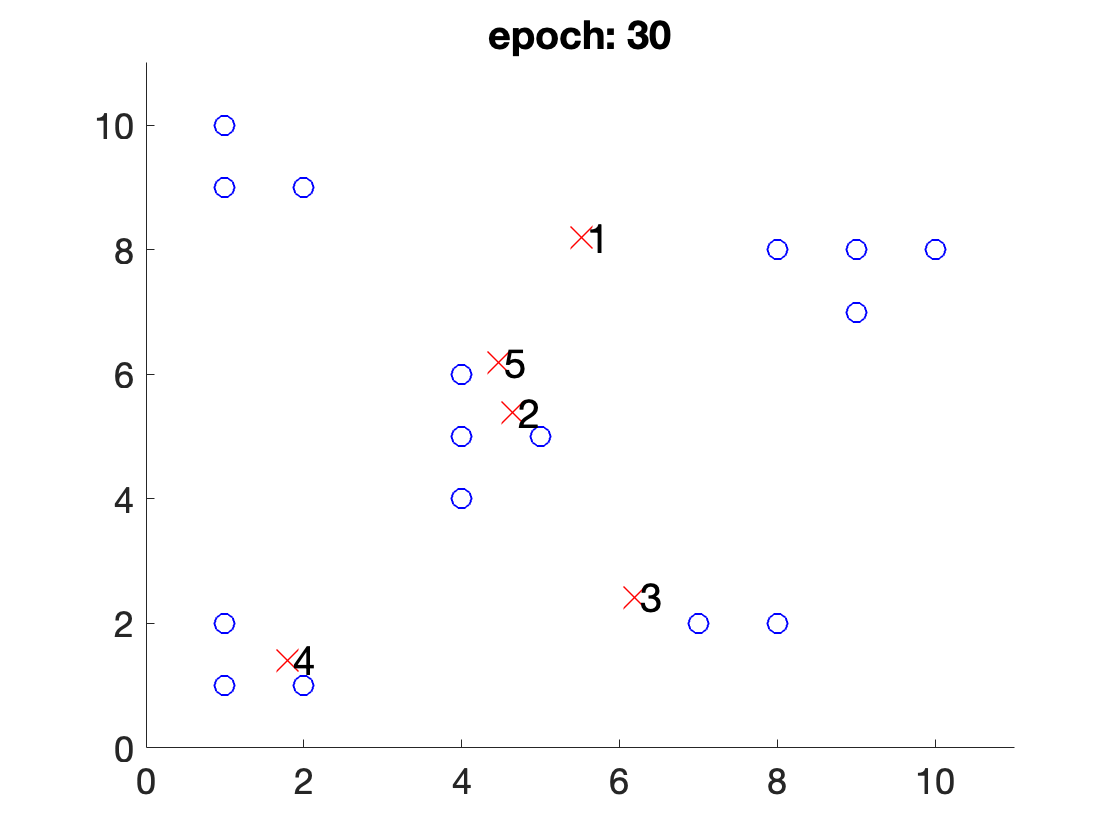

% initialize plot
set(0,'defaulttextfontsize',18); set(0,'defaultaxesfontsize',18);
figure; clf; hold on; title(['epoch: ' num2str(iepoch)])
xlim([0 11]); ylim([0 11]);

% plot datapoints
scatter(X(1,:),X(2,:),100,'bo');

% plot reference points:
href=scatter(Xref(1,:),Xref(2,:),200,'rx');
for ii=1:N_grid 
  h_ref_text(ii)=text(Xref(1,ii)+0.07,Xref(2,ii),num2str(ii),'FontSize',20);
end
hold off

## 1b

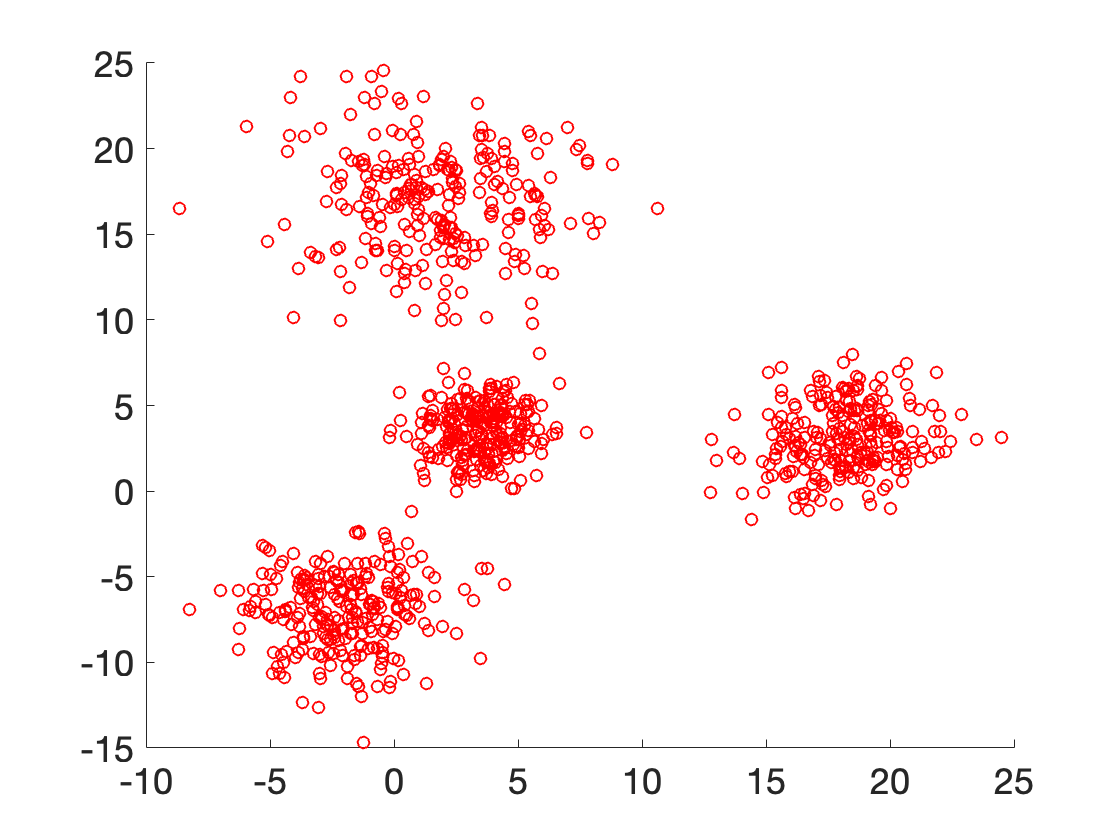

% Matlab
rng(2021); N=250; X=zeros(2,4*N);
for i=1:N; X(:,i)=[5,5]' +(1.5*(randn(2,1)-1)); end;
for i=N+1:2*N; X(:,i)=[0,-5]'+(2.0*(randn(2,1)-1));end;
for i=2*N+1:3*N; X(:,i)=[5,20]'+(3.0*(randn(2,1)-1));end;
for i=3*N+1:4*N; X(:,i)=[20,5]'+(2.0*(randn(2,1)-1));end;
p=randperm(4*N); X=X(:,p);figure(1); clf; scatter(X(1,:),X(2,:),'r')

Adapted from "self_organizing_maps_library_function_example.m"

nx=2; ny=3;

fprintf(1,' SOM geometry is (nx,ny)=(%d,%d).\n',nx,ny)

 SOM geometry is (nx,ny)=(2,3).


% specify geometry of SOM:
net = selforgmap([nx ny]);
% train the network to find clusteroids:
net = train(net,X);
% examine network:
view(net);
% classify, Y is a set of vectors (y1,...yn), one per each data point,
% containing cluster assignments for all data points, e.g.,
% assuming four clusters, if y_i=[0,1,0,0], then the
% corresponding i'th data point belongs to cluster 2:
Y = net(X);
% classes is a single vector contain the cluster assignments of all
% data points: if classes(i)=2, point i belongs to cluster 2:
classes = vec2ind(Y);

Plot clusters:

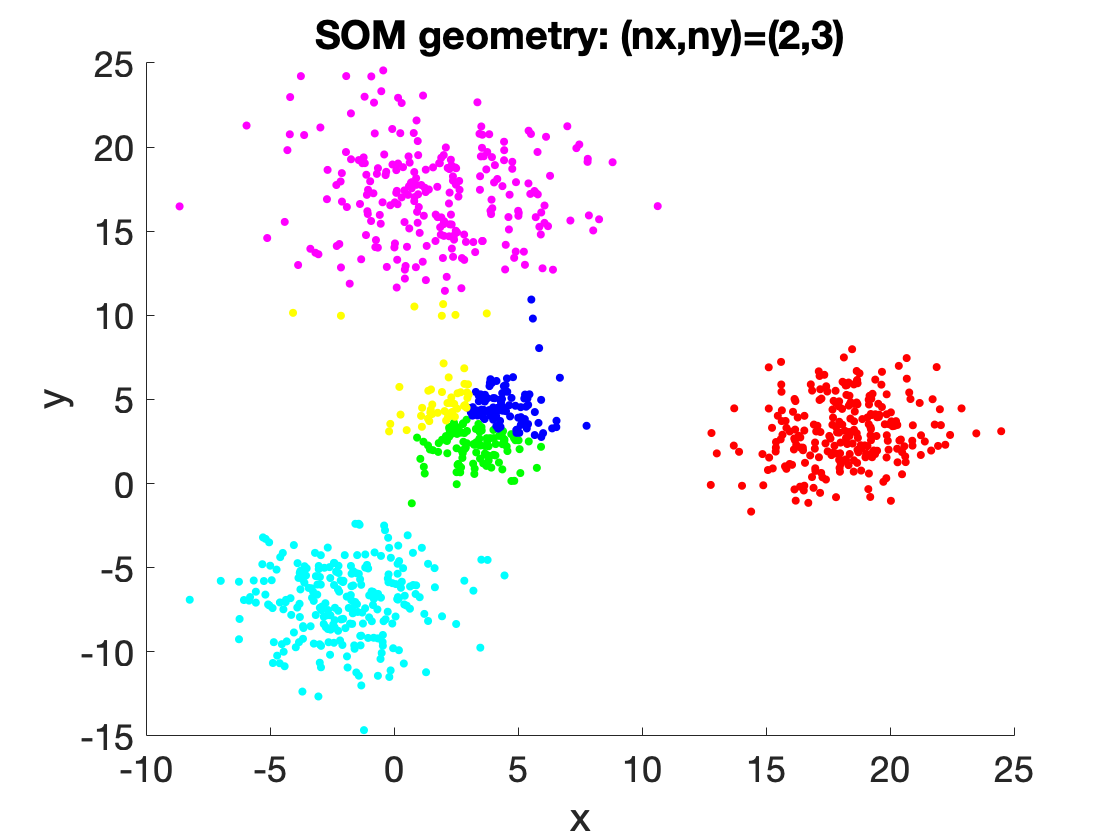

% plot clusters in different colors:
figure; clf; hold on
color ='rgbcmyrgbcmyrgbcmyrgbcmy';
marker='......xxxxxx++++++oooooo';
Nmaps=nx*ny;
for i=1:1:Nmaps
    plot(X(1,classes==i),X(2,classes==i),[color(i) marker(i)],'MarkerSize',12)
end
xlabel('x');
ylabel('y');
title(sprintf('SOM geometry: (nx,ny)=(%d,%d)',nx,ny));
hold off

## 2

X=[0.5,1.5,0.5,1,9,7.5,7,9.5,1.5,1,1,8.5,9.5,6.5,8,0.5,1,9,9.5,7,10,1.5,8.5,9.5;
9.5,8.5,0.5,1,0.5,5.5,4.5,9.5,9.5,0.5,1.5,0.5,1,5.5,4.5,9,9,9.5,9,5,9.5,0.5,1,8.5];

Initial plot:

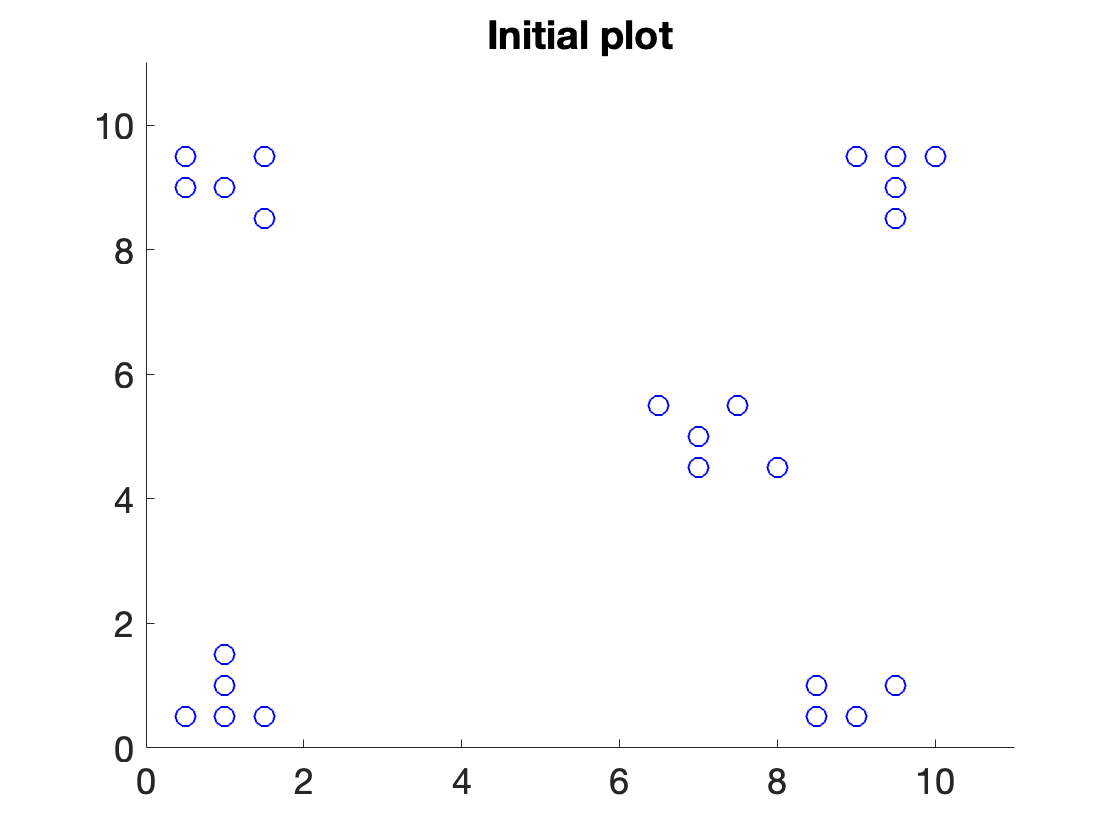

set(0,'defaulttextfontsize',18); set(0,'defaultaxesfontsize',18);
figure; clf; hold on; title('Initial plot')
xlim([0 11]); ylim([0 11]);
color ='rgbcmyrgbcmyrgbcmyrgbcmy';
marker='......xxxxxx++++++oooooo';

% plot datapoints
scatter(X(1,:),X(2,:),100,'bo');
hold off

Adapted from "spectral_clustering_example.m"

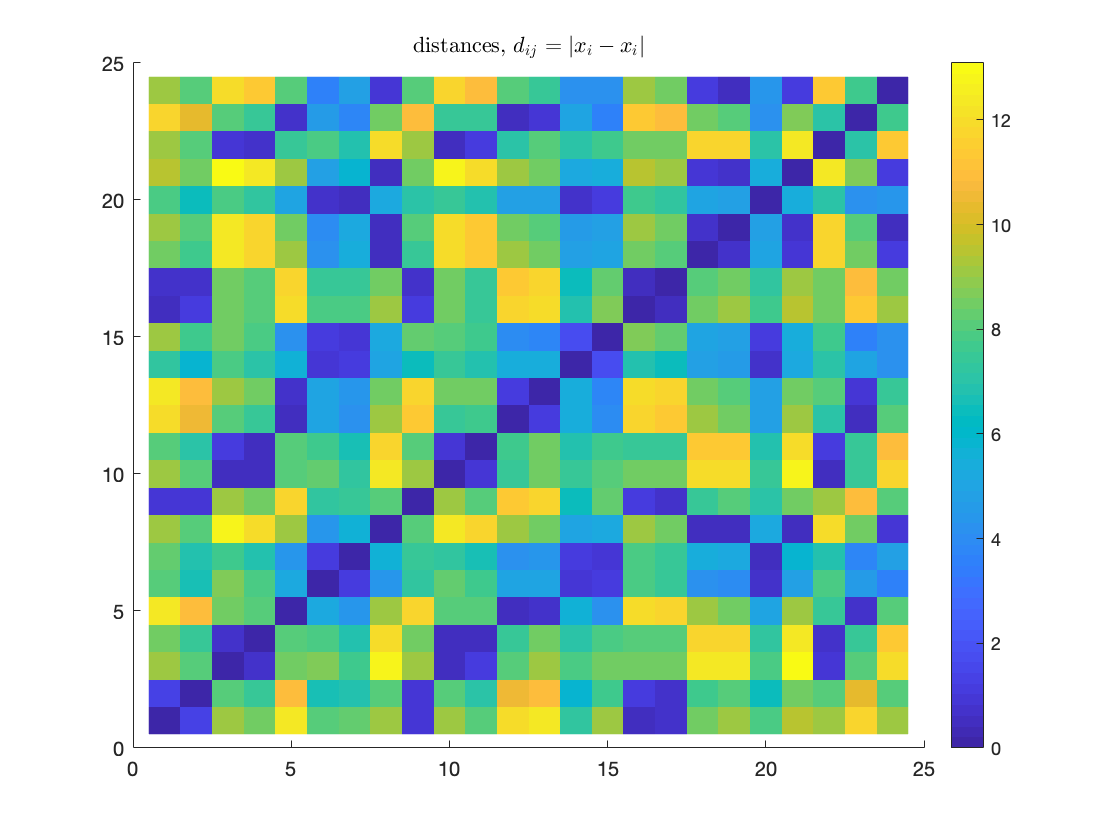

% Calculate distances between all pairs of points:
Y = pdist(X.','euclid'); % or could use, for example, Y = pdist(X,'minkowski',1);
distances=squareform(Y);
figure; hold on
imagesc(distances); colorbar
title('distances, $d_{ij}=|x_i-x_i|$','Interpreter','LaTeX')
hold off

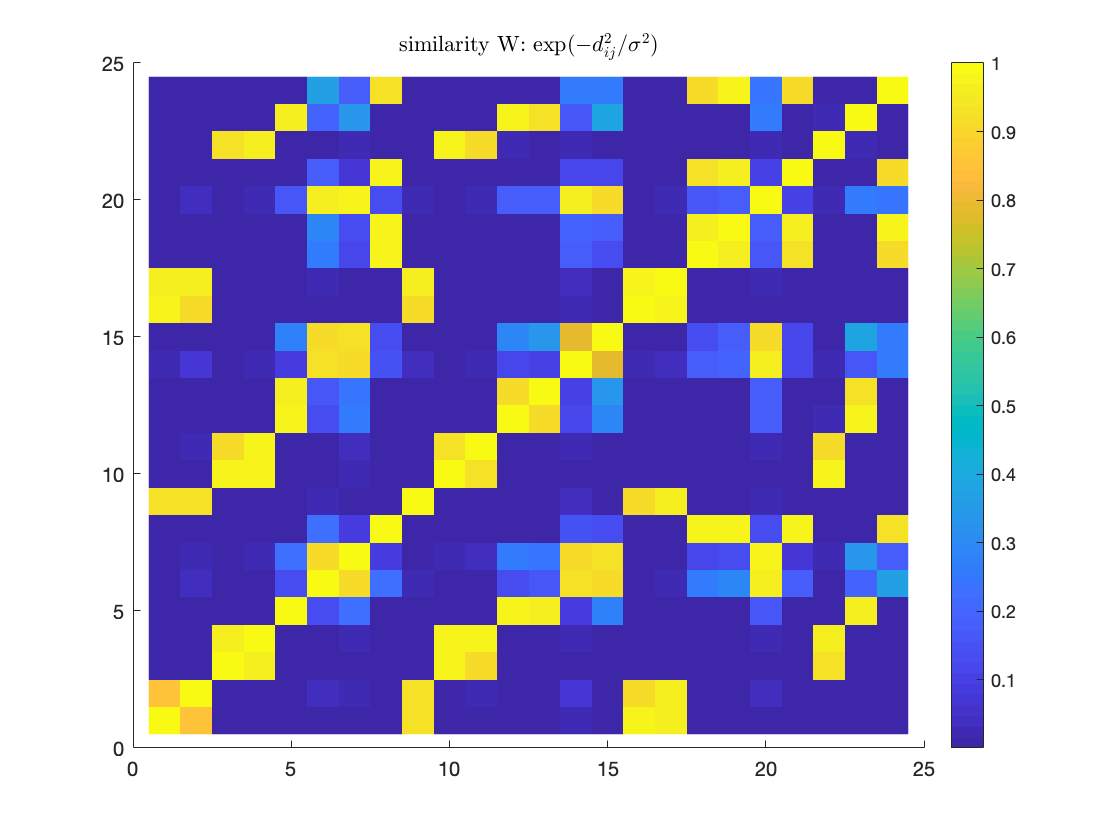


% build similarity matrix from distances (Luxburg 2007):
dists_std=std(distances(:)); % std of distances
W=exp(-distances.^2/dists_std^2);
figure; hold on
imagesc(W); colorbar
title('similarity W: $\exp(-d_{ij}^2/\sigma^2)$','Interpreter','LaTeX')
hold off

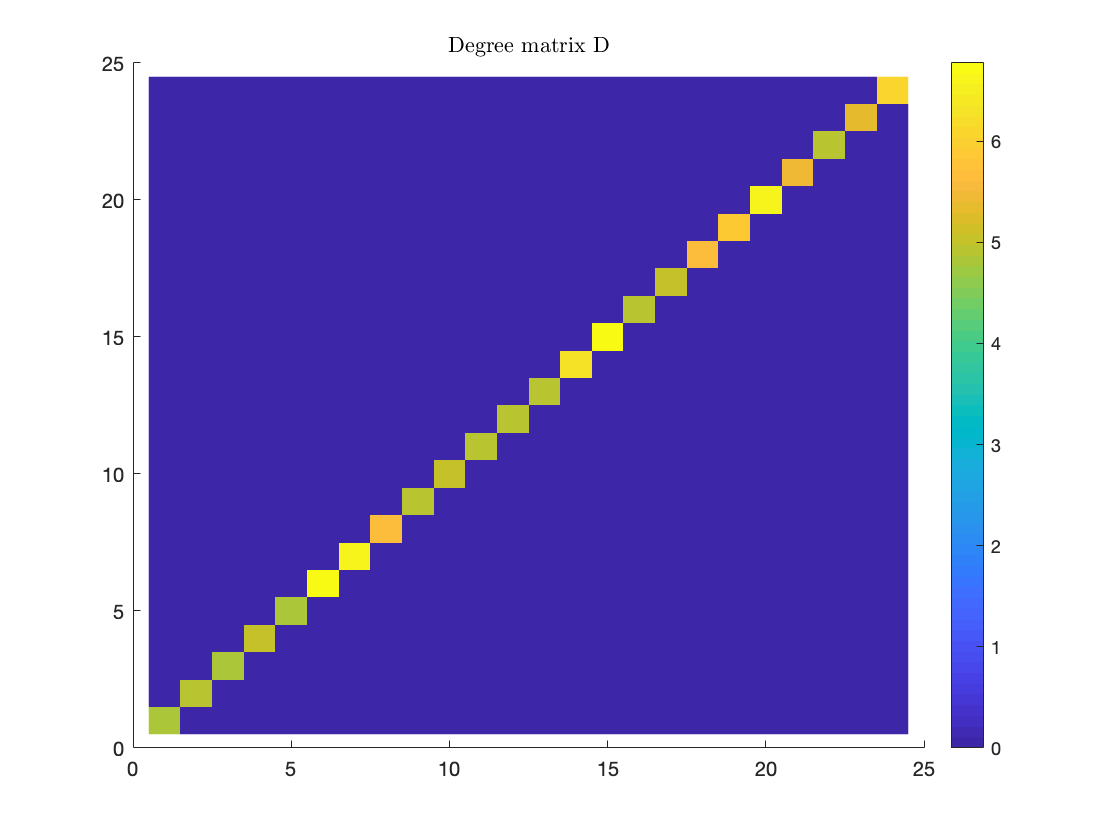


% degree matrix is some over rows of adjacency matrix:
D=diag(sum(W));
figure; hold on
imagesc(D); colorbar
title('Degree matrix D','Interpreter','LaTeX')
hold off

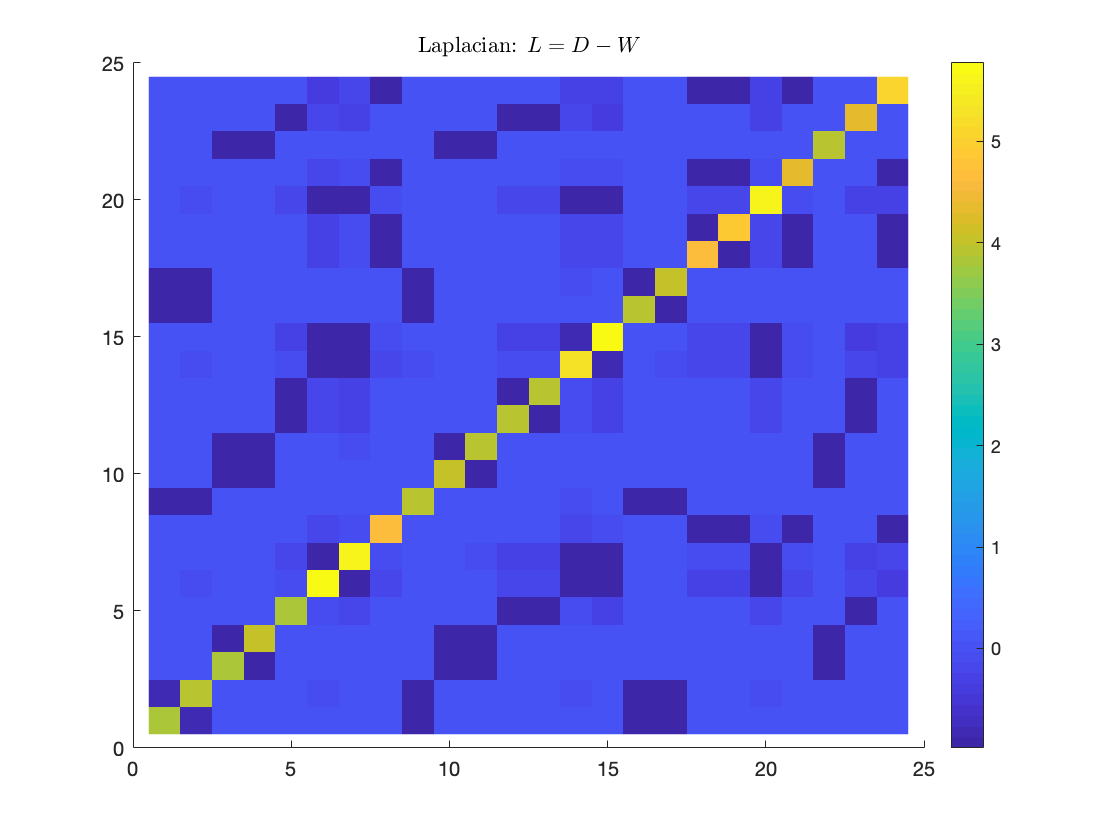


% Laplacian matrix:
L=D-W;
figure; hold on
imagesc(L); colorbar
title('Laplacian: $L=D-W$','Interpreter','LaTeX')
hold off

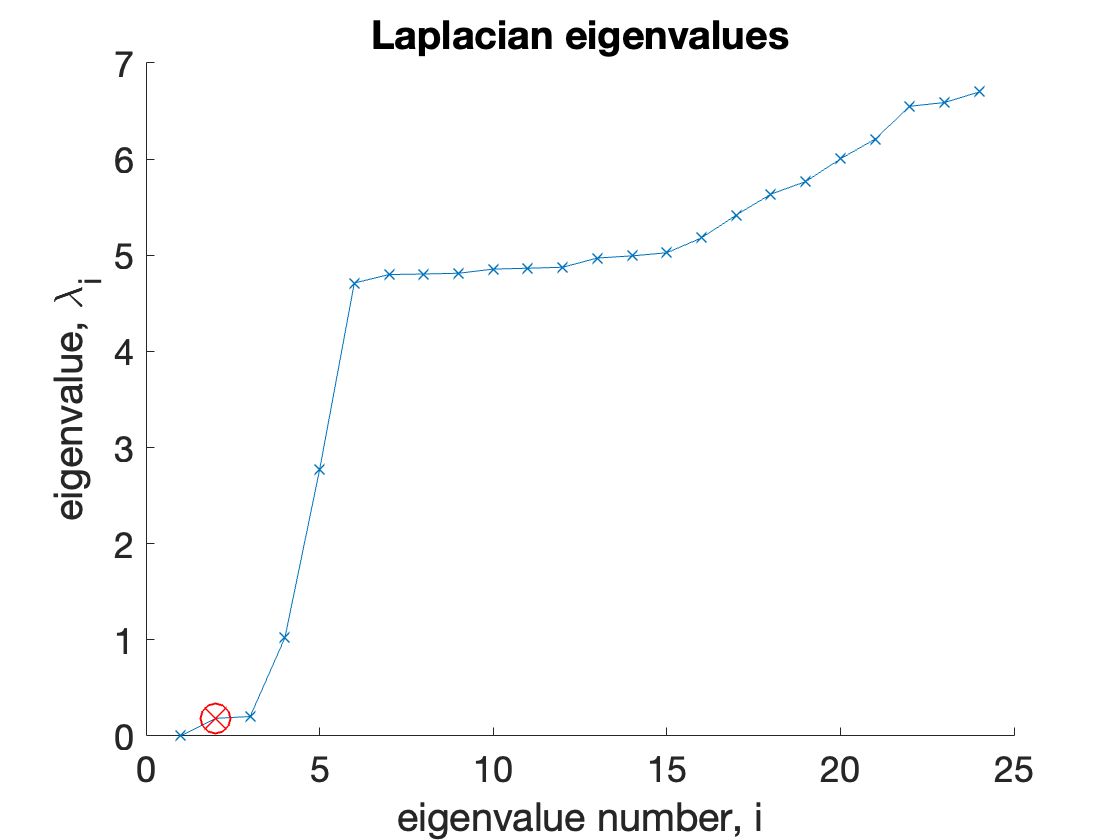


% calculate eivenvectors of Laplacian matrix:
[V,D] = eig(L);

figure; hold on
d=diag(D);
plot(d,'-x');
% highlight second smallest eigenvalue:
plot(2,d(2),'ro','markersize',15);
plot(2,d(2),'rx','markersize',15);
xlabel('eigenvalue number, i')
ylabel('eigenvalue, \lambda_i')
title('Laplacian eigenvalues');
hold off

There seems to be a spectral gap around k=5, so we can try that

k=5

k = 5

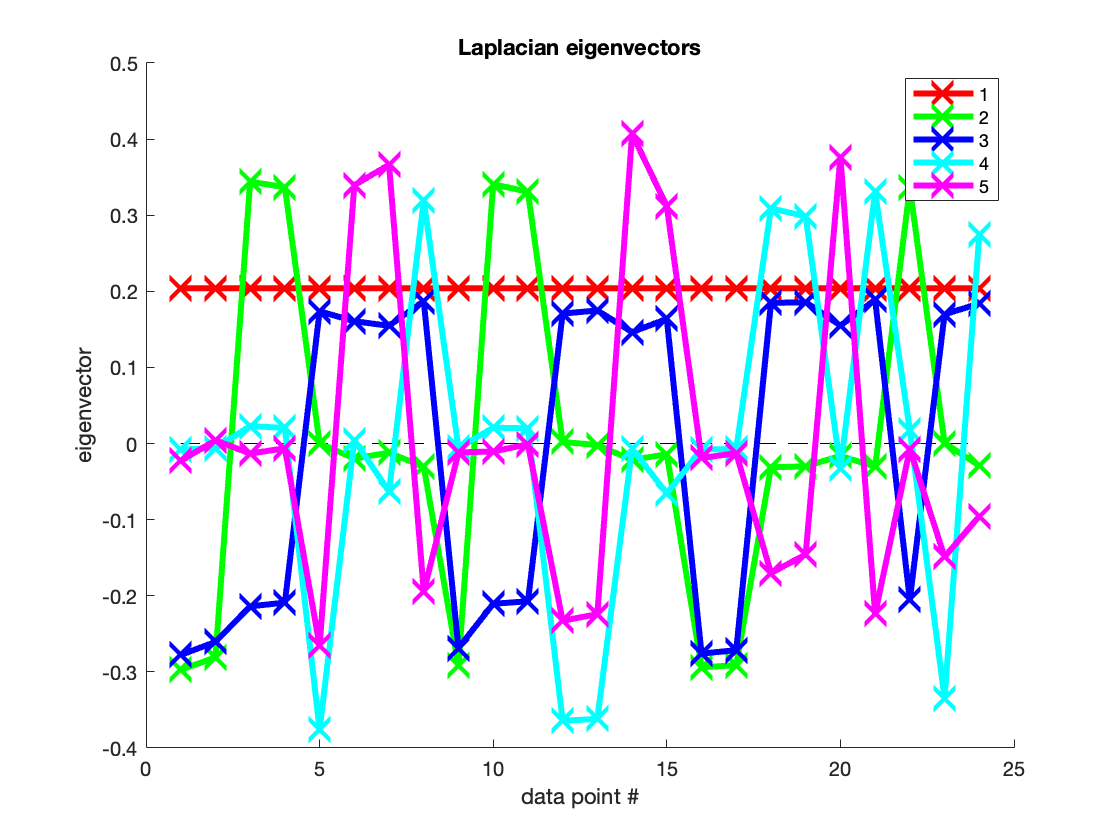


figure; hold on
plot(0*V(:,1),'--k','linewidth',0.5);
for ii=1:k
  hl(ii)=plot(V(:,ii),[color(ii) 'x-']);
  if ii>=2; set(hl,'linewidth',3,'markersize',15); end
  legend_text(ii)=sprintf('%d',ii);
end
title(sprintf('Laplacian eigenvectors',k));
xlabel('data point #')
ylabel('eigenvector')
legend([hl(:)],legend_text(:));
hold off

[why we may expect these Laplacian eigenvectors to be helpful in clustering the data.]

k-means Clustering:

opts = statset('Display','final');
[idx,C] = kmeans(V(:,2:k),k,'Distance','sqeuclidean' ...
               ,'Replicates',5,'Options',opts);

Replicate 1, 1 iterations, total sum of distances = 0.0302072.
Replicate 2, 1 iterations, total sum of distances = 0.0302072.
Replicate 3, 1 iterations, total sum of distances = 0.0302072.
Replicate 4, 1 iterations, total sum of distances = 0.0302072.
Replicate 5, 1 iterations, total sum of distances = 0.0302072.
Best total sum of distances = 0.0302072


Plot clusters in dataspace:

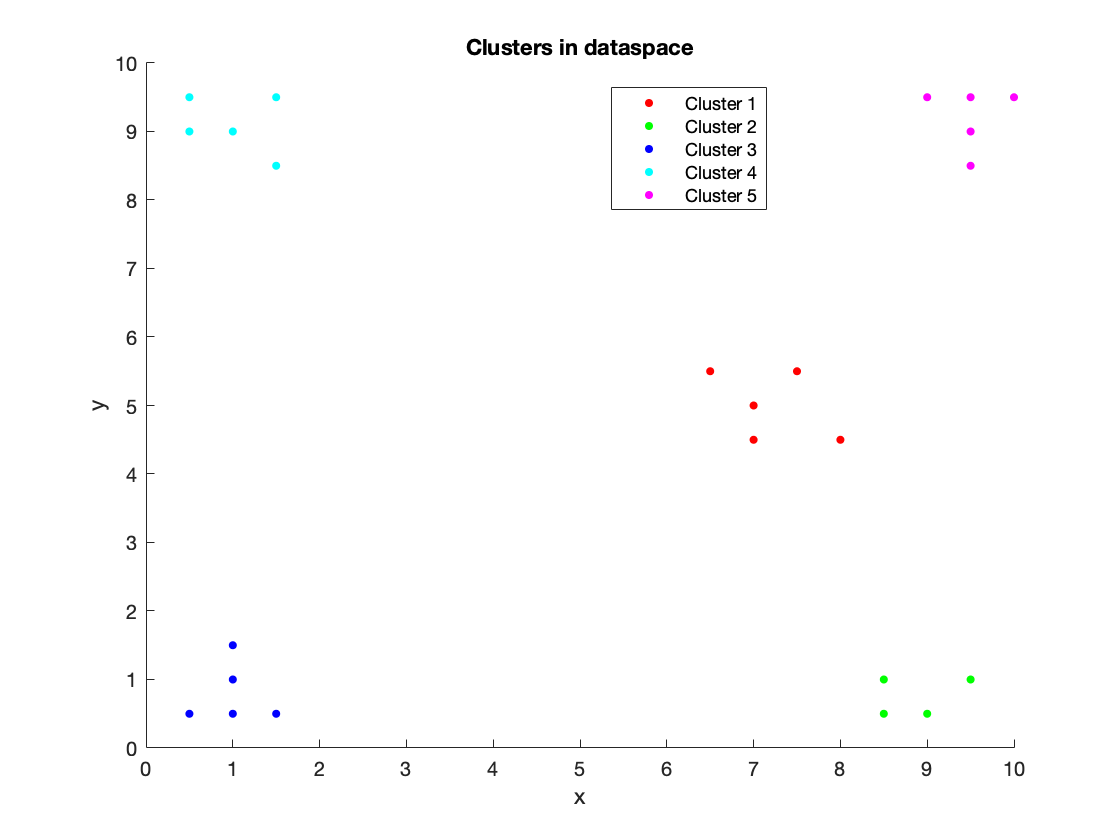

figure;hold on
for i=1:1:k
  plot(X(1,idx==i),X(2,idx==i),[color(i) marker(i)],'MarkerSize',12)
end
% write legend:
for i=1:1:k
  if i<10
    legends(i,:)=['Cluster ' num2str(i)];
  else
    legends(i,:)=['Cluster' num2str(i)];
  end
end
legend(legends,'Location','best');
title(sprintf('Clusters in dataspace'));
xlabel('x');
ylabel('y');    
hold off

Plot clusters in eigenspace: [check which eigenvectors and k]

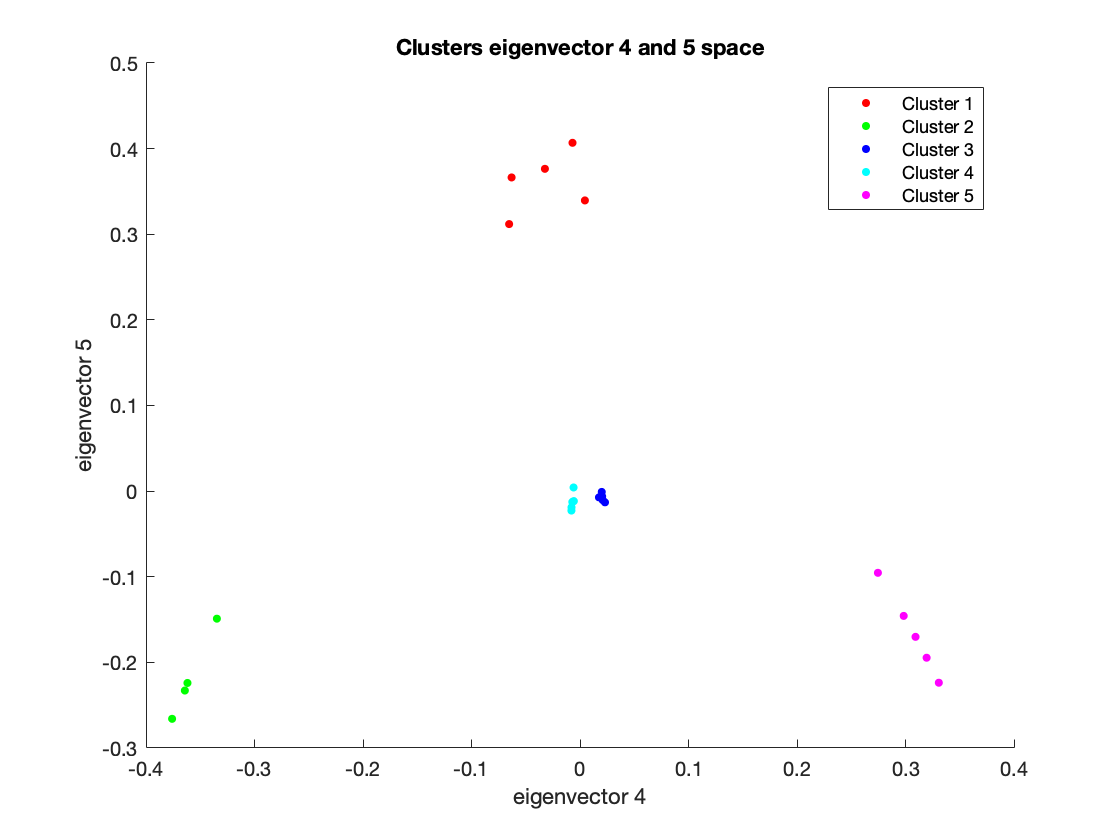

% draw clusters in eigenvector space:
figure; hold on
for i=1:k
plot(V(idx==i,4),V(idx==i,5),[color(i) marker(i)],'MarkerSize',12)
end
legend(legends,'Location','best');
title(sprintf('Clusters eigenvector 4 and 5 space'));
xlabel('eigenvector 4');
ylabel('eigenvector 5');

## 3a

clear all
load 'HW08_CURE.mat'

Initial plot:

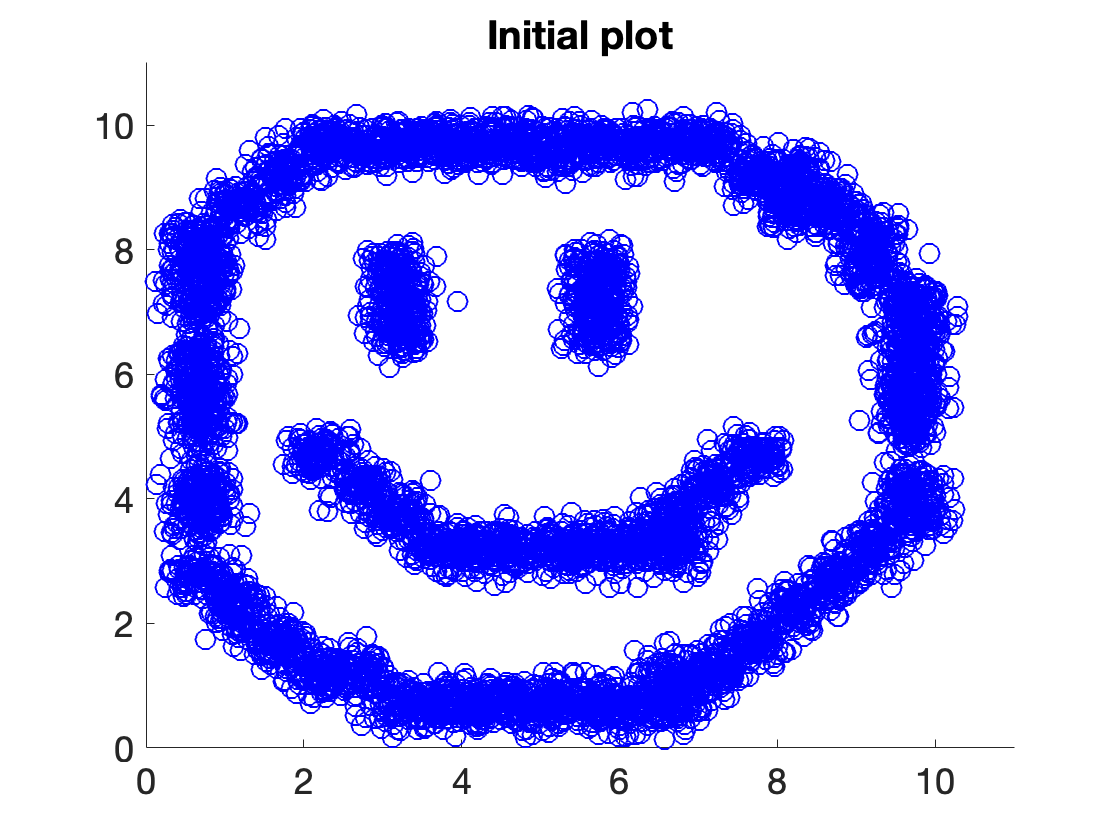

set(0,'defaulttextfontsize',18); set(0,'defaultaxesfontsize',18);
figure; clf; hold on; title('Initial plot')
xlim([0 11]); ylim([0 11]);
color ='rgbcmyrgbcmyrgbcmyrgbcmy';
marker='......xxxxxx++++++oooooo';

% plot datapoints
scatter(X(1,:),X(2,:),100,'bo');
hold off

Cute :)

Single:

Y=pdist(X');
distances=squareform(Y)

distances =          0    0.2556    0.2975    0.5334    0.4553    0.2999    0.5421    0.5863    0.2061    0.7689    0.4404    0.1201    0.2816    0.2223    0.5407    0.8164    0.3404    0.2502    0.3779    0.2464    0.3076    0.2753    0.5676    0.9971    0.3316    0.7255    0.4939    0.3310    0.2464    0.2563    0.5255    0.2400    0.3036    0.7567    0.3433    0.4588    0.8797    0.4455    0.3175    0.3583    0.3172    0.2253    0.3424    0.1370    0.8327    0.3379    0.4517    0.4336    0.3509    0.5898
    0.2556         0    0.2673    0.5753    0.5156    0.2619    0.6627    0.6366    0.3657    0.6407    0.3945    0.3579    0.2052    0.1569    0.5351    0.7996    0.3374    0.4094    0.3304    0.3987    0.4559    0.3822    0.7948    0.9464    0.1626    0.8470    0.2386    0.4094    0.1021    0.3329    0.5949    0.2765    0.3489    0.9384    0.3584    0.5700    0.7570    0.1915    0.4090    0.4447    0.3366    0.4694    0.5166    0.3800    0.9775    0.3689    0.2901    0.3356    0.3

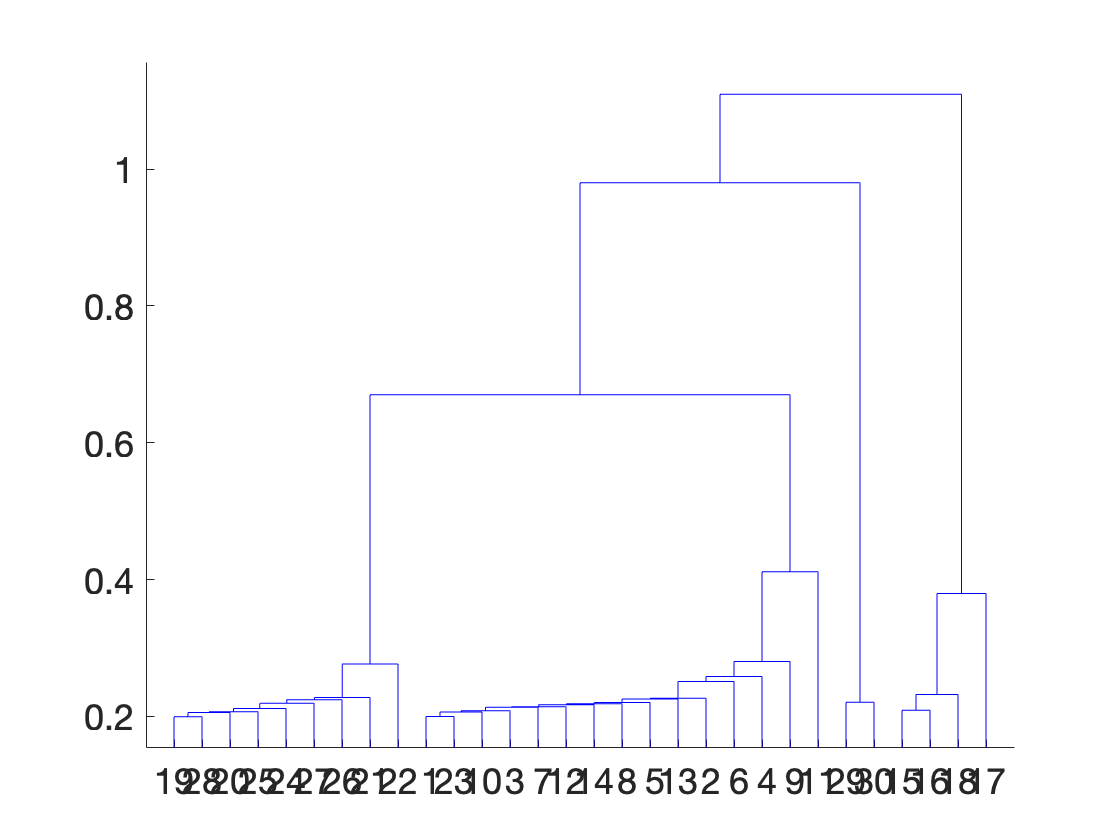

Z=linkage(Y,'single');
dendrogram(Z);

Seems like a pretty big jump @4 clusters

k=4

k = 4

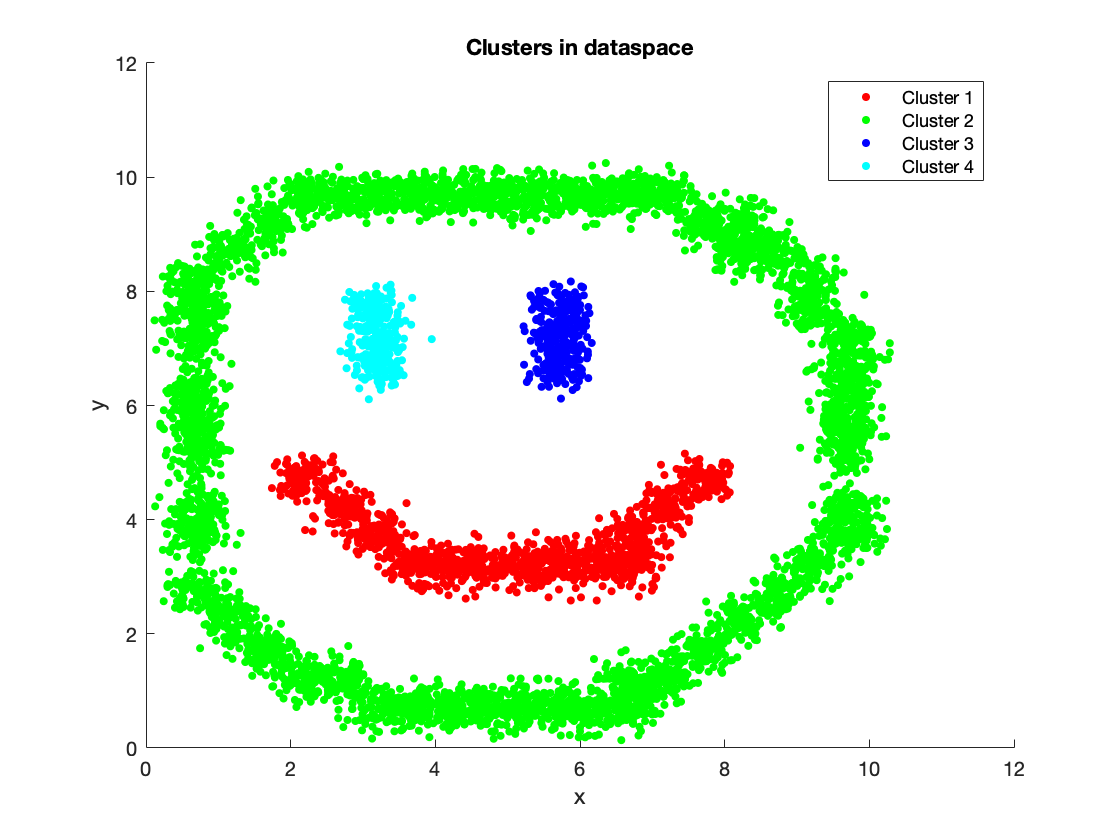

idx=cluster(Z,'maxclust',k)';
figure;hold on
for i=1:1:k
  plot(X(1,idx==i),X(2,idx==i),[color(i) marker(i)],'MarkerSize',12)
end
% write legend:
for i=1:1:k
  if i<10
    legends(i,:)=['Cluster ' num2str(i)];
  else
    legends(i,:)=['Cluster' num2str(i)];
  end
end
legend(legends,'Location','best');
title(sprintf('Clusters in dataspace'));
xlabel('x');
ylabel('y');    
hold off

Centroid:

Z=linkage(Y,'centroid');

distances =          0    0.2556    0.2975    0.5334    0.4553    0.2999    0.5421    0.5863    0.2061    0.7689    0.4404    0.1201    0.2816    0.2223    0.5407    0.8164    0.3404    0.2502    0.3779    0.2464    0.3076    0.2753    0.5676    0.9971    0.3316    0.7255    0.4939    0.3310    0.2464    0.2563    0.5255    0.2400    0.3036    0.7567    0.3433    0.4588    0.8797    0.4455    0.3175    0.3583    0.3172    0.2253    0.3424    0.1370    0.8327    0.3379    0.4517    0.4336    0.3509    0.5898
    0.2556         0    0.2673    0.5753    0.5156    0.2619    0.6627    0.6366    0.3657    0.6407    0.3945    0.3579    0.2052    0.1569    0.5351    0.7996    0.3374    0.4094    0.3304    0.3987    0.4559    0.3822    0.7948    0.9464    0.1626    0.8470    0.2386    0.4094    0.1021    0.3329    0.5949    0.2765    0.3489    0.9384    0.3584    0.5700    0.7570    0.1915    0.4090    0.4447    0.3366    0.4694    0.5166    0.3800    0.9775    0.3689    0.2901    0.3356    0.3

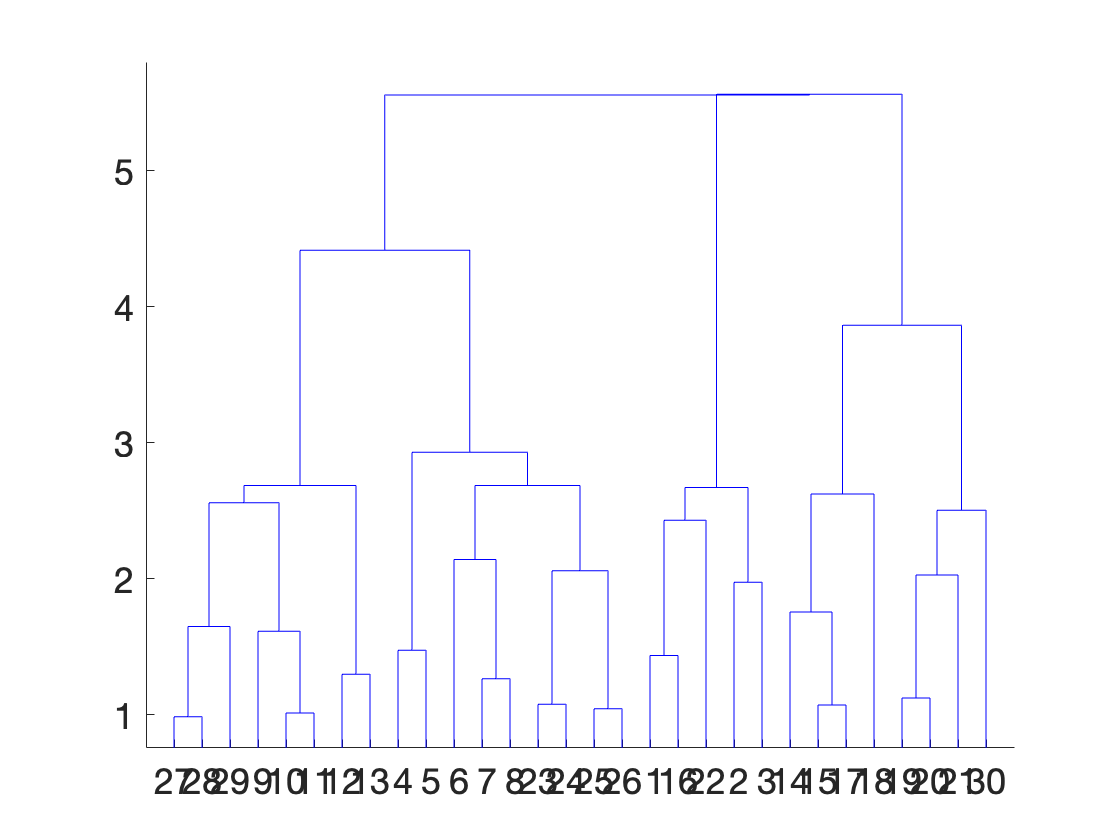

dendrogram(Z);

Jump could be @k=4 still kind of

k=4

k = 4

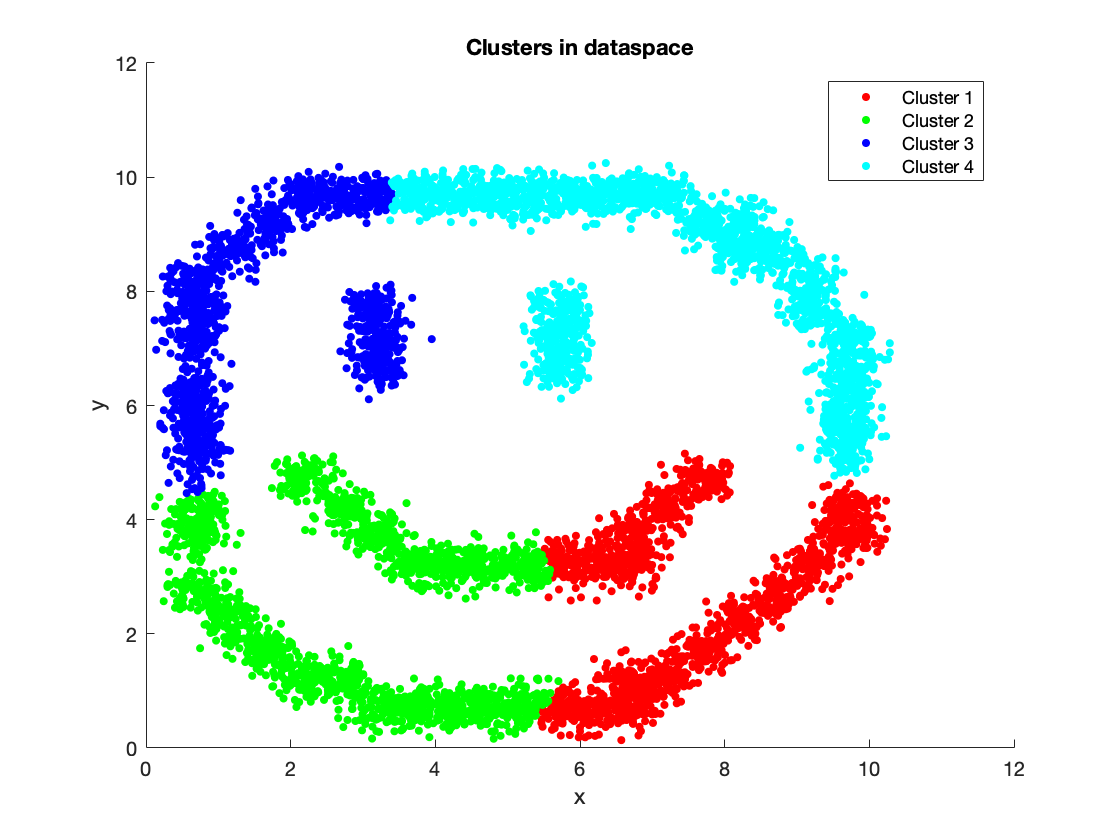

idx=cluster(Z,'maxclust',k)';
figure;hold on
for i=1:1:k
  plot(X(1,idx==i),X(2,idx==i),[color(i) marker(i)],'MarkerSize',12)
end
% write legend:
for i=1:1:k
  if i<10
    legends(i,:)=['Cluster ' num2str(i)];
  else
    legends(i,:)=['Cluster' num2str(i)];
  end
end
legend(legends,'Location','best');
title(sprintf('Clusters in dataspace'));
xlabel('x');
ylabel('y');    
hold off

So centroid isn't going to be great here since [why is centroid not gonna be great]

But single is better for clusters within clusters as long as they don't have any points or parts touching/too close to each other. [why, go more in depth]

## 3b

clear all
load 'HW08_CURE.mat'

Random initial representative points:

[M,N]=size(X);
n_reps=300;
rand_cols = randperm(N,n_reps);
rand_reps = X(:,rand_cols);

Hierarchical clustering of rand_reps:

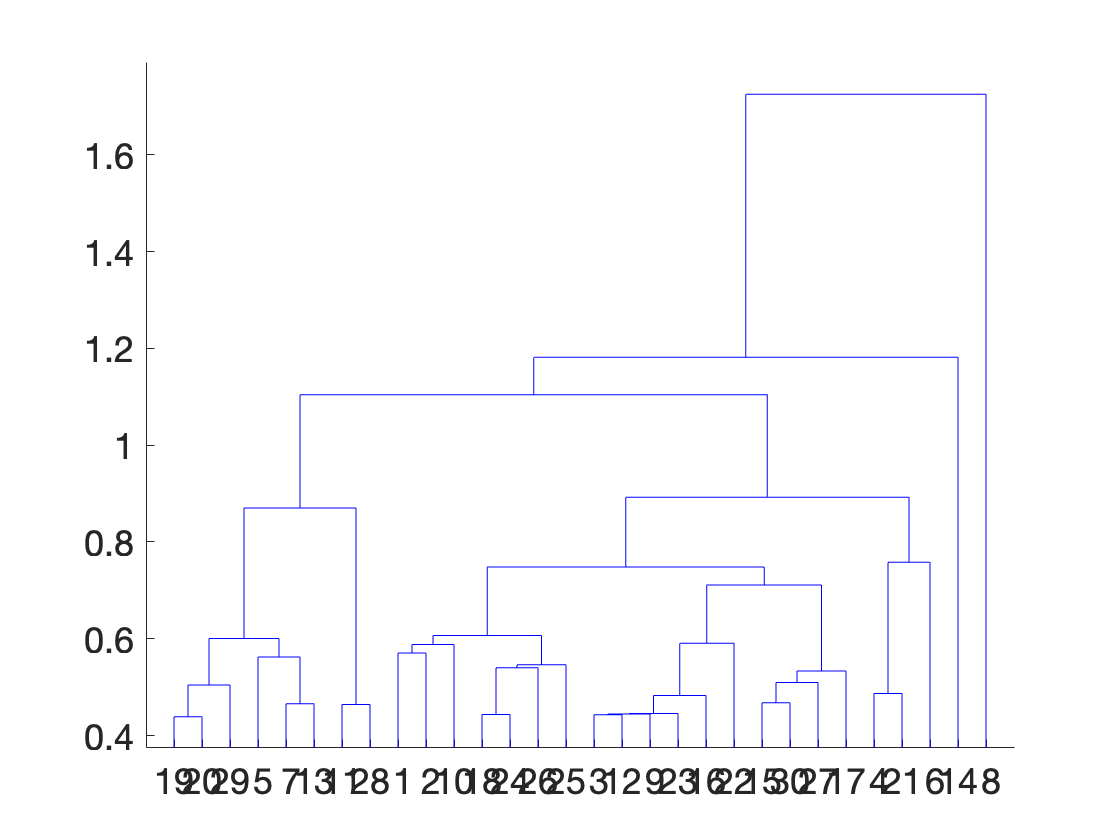

Y=pdist(rand_reps','euclid'); 
Z=linkage(Y,'single');
dendrogram(Z);

Jump around k=4

k=4;
idx_rand_reps = cluster(Z,'maxclust',k);

Everyone go find your rand_rep point that's closest:

all_dists=zeros([1 n_reps]);
for i=1:N
  for j=1:n_reps
    all_dists(1,j)=norm(X(:,i)-rand_reps(:,j));
  end
  [M,nearest_rand_rep] = min(all_dists);
  idx(i)=idx_rand_reps(nearest_rand_rep);
end

Plot:

figure;hold on
color ='rgbcmyrgbcmyrgbcmyrgbcmy';
marker='......xxxxxx++++++oooooo';
for i=1:1:k
  plot(X(1,idx==i),X(2,idx==i),[color(i) marker(i)],'MarkerSize',12)
end
% write legend:
for i=1:1:k
  if i<10
    legends(i,:)=['Cluster ' num2str(i)];
  else
    legends(i,:)=['Cluster' num2str(i)];
  end
end
legend(legends,'Location','best');
title(sprintf('Clusters in dataspace'));
xlabel('x');
ylabel('y');

Plot representatives:

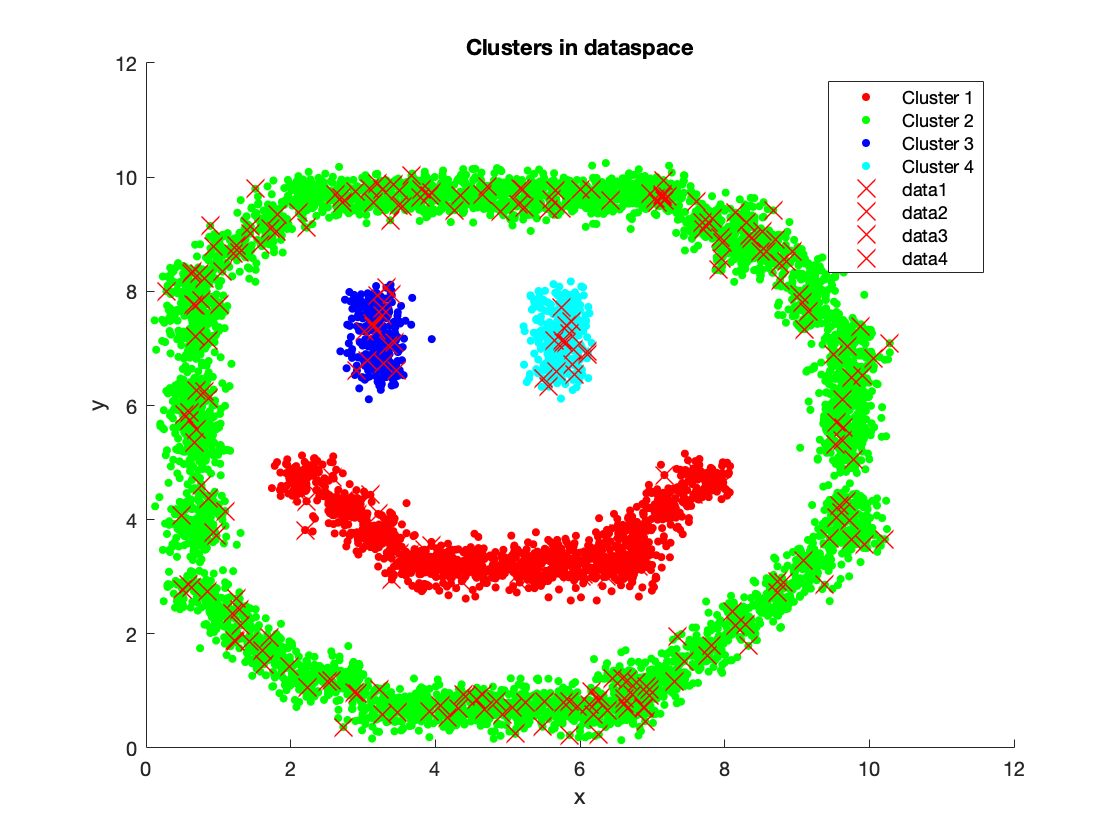

for i=1:1:k
  plot(rand_reps(1,idx_rand_reps==i),rand_reps(2,idx_rand_reps==i),'rx','MarkerSize',12)
end
hold off